# Lesson 2

Written by Brenda So and Cory Nezin

# Objective

After this class, you should be able to:

- Understand how to perform vector operations in MATLAB

- Understand arithmetic and basic functions in MATLAB

- Know how to use for statements

# Vector Operations

In lesson 1, we see how to make a vector with the colon operator and linspace, however, if MATLAB only allows us to use these two operations on vectors, it would be pretty useless. MATLAB is often used to perform numerical analysis, hence it would be very useful if we can input vectors into functions and use that to generate another vector. Luckily, that's what MATLAB is for! Note that when you perform an operation, they are element wise operation for vectors. 

x = 0:0.01:2*pi;    % You create a vector
y = sin(x);         % Here, you perform a transformation from one vector to another
xlen = length(x)

xlen = 629

ylen = length(y)    % xlen and ylen is equal!

ylen = 629

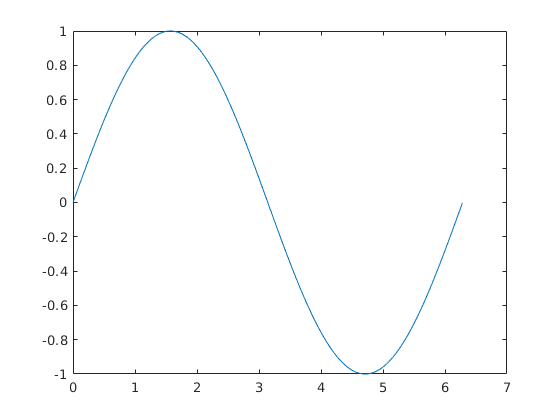

plot(x,y)

## Exercise 1 : Vector Operations

Create a vector t, where t ranges from 0 to 2 millisecond with increments T = 1e-6, and create another vector y1, where $f_{0\text{ }} =50\text{ }Hz$ and $\beta =10\text{ }M\text{Hz}\text{ }s^{-1}$


$$y_1 \left(t\right)=10cos\left(2\pi f_{0\text{ }} t+\pi \beta t^2 \right)$$


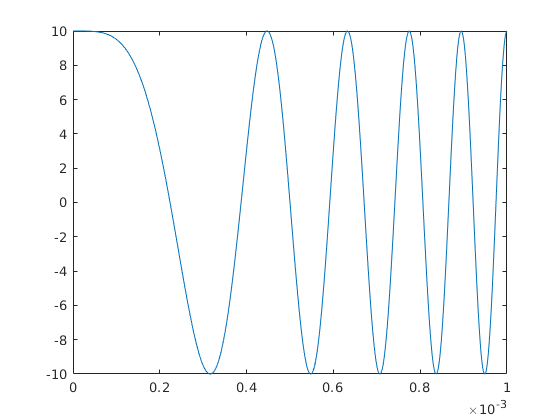

t = 0:1e-6:1e-3;
f0 = 50;
beta = 10e6;
y1 = 10*cos(2*pi*f0 + pi*beta*t.^2);
figure;
plot(t,y1)

# Basic Indexing in MATLAB

To inspect certain values in vectors x and y, we can use indexing. Now we are going to delve deeper into indexing next week, but here we are going to give you enough information to do the homework assignment

## Exercise 2 : Basic Indexing

x(:)

ans =    -2.0000
   -1.9596
   -1.9192
   -1.8788
   -1.8384
   -1.7980
   -1.7576
   -1.7172
   -1.6768
   -1.6364


x(1)

ans = -2

x(5)

ans = -1.8384

x(2:5)

ans =    -1.9596   -1.9192   -1.8788   -1.8384


x(end)

ans = 2

## BE CAREFUL!

In other languages, indices start at 0, however, in MATLAB, indices start at 1. Hence in matlab, the last index would be the length of the vector itself. 

# Other vector operations

Of course, we can perform more complicated arithmetic operations on vectors, just like what we can do with scalars. What's more, there are pre-built functions in matlab that allows us to obtain certain statistics. There's a lot of such functions but we are only showing a few commonly used operations here

## Exercise 3 : Other vector operations

% WRITEME: calculate sum of x
% WRITEME: calculate average of x
% WRITEME: calculate minimum in x
% WRITEME: calculate difference between adjacent elements in x

# Practical example of vector operations : Numerical Estimation of integrals and derivatives

## Approximate Derivatives

Here we will look at some approximate numerical methods

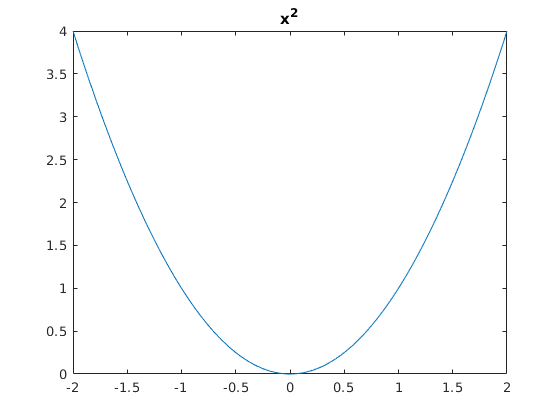

x = linspace(-2,2,100);
y = x.^2;
plot(x,y)
title('x^2')

Now, we can approximate the derivative


$$\frac{dy}{dx}=\lim_{\Delta x\to 0} \frac{y\left(x+\Delta x\right)-y\left(x\right)}{\Delta x}$$


as


$$\hat{\frac{\text{dy}}{\text{dx}}} =\frac{y\left(x+\Delta x\right)-y\left(x\right)}{\Delta x}=\frac{\Delta y}{\Delta x}$$


where$\Delta x$ is small

An easy way to do this in MATLAB is the *diff* command which returns the difference between every pair of consecutive numbers in a vector (or each column of an array).

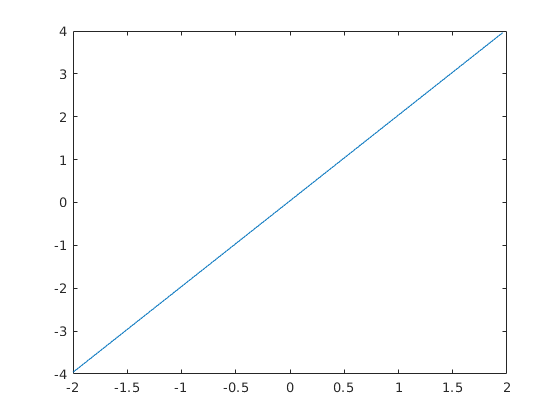

dydx = diff(y)./diff(x);
plot(x(1:end-1),dydx)

 *diff *returns one less element than the original vector, this simple strategry returns an error.  Fix this by plotting against a new x, *xhat.  *Note that there are many valid ways to do this. You will need *xhat *later so make sure you get it!

## Excercise 4: Approximate Derivative

xhat = x(1:end-1)

xhat =    -2.0000   -1.9596   -1.9192   -1.8788   -1.8384   -1.7980   -1.7576   -1.7172   -1.6768   -1.6364   -1.5960   -1.5556   -1.5152   -1.4747   -1.4343   -1.3939   -1.3535   -1.3131   -1.2727   -1.2323   -1.1919   -1.1515   -1.1111   -1.0707   -1.0303   -0.9899   -0.9495   -0.9091   -0.8687   -0.8283   -0.7879   -0.7475   -0.7071   -0.6667   -0.6263   -0.5859   -0.5455   -0.5051   -0.4646   -0.4242   -0.3838   -0.3434   -0.3030   -0.2626   -0.2222   -0.1818   -0.1414   -0.1010   -0.0606   -0.0202


plot(xhat,dydx)

## Approximate Integrals

Now suppose we want to approximate the cumulative integral of a function, i.e.


$$Y\left(u\right)=\int_c^u y\left(x\right)dx=\lim_{\Delta x\to 0} \text{  }\sum_{c+n\Delta x\text{ }\in \left\lbrack c,u\right\rbrack } y\left(c+n\Delta x\right)\Delta x\text{ }$$


Again, we can approximate this by simply dropping the limit


$$\hat{Y} =\sum_{c+n\Delta x\text{ }\in \left\lbrack c,u\right\rbrack } y\left(c+n\Delta x\right)\Delta x\text{ }$$


The *cumsum* function in MATLAB returns the running sum of a vector, i.e.


$${cumsum\left(v\right)}_{1,n} =\sum v\left(1:n\right)$$


Use *cumsum* to approximate the running integral of y.  Again, there are a few valid ways of doing this.

## Excercise 5. Cumulative Integral

Y = cumsum(y).*(x(2)-x(1))

Y =     0.1616    0.3168    0.4656    0.6082    0.7448    0.8754    1.0002    1.1193    1.2329    1.3411    1.4440    1.5418    1.6345    1.7224    1.8055    1.8841    1.9581    2.0277    2.0932    2.1546    2.2120    2.2655    2.3154    2.3617    2.4046    2.4442    2.4806    2.5140    2.5445    2.5722    2.5973    2.6199    2.6401    2.6581    2.6739    2.6878    2.6998    2.7101    2.7188    2.7261    2.7320    2.7368    2.7405    2.7433    2.7453    2.7466    2.7474    2.7479    2.7480    2.7480


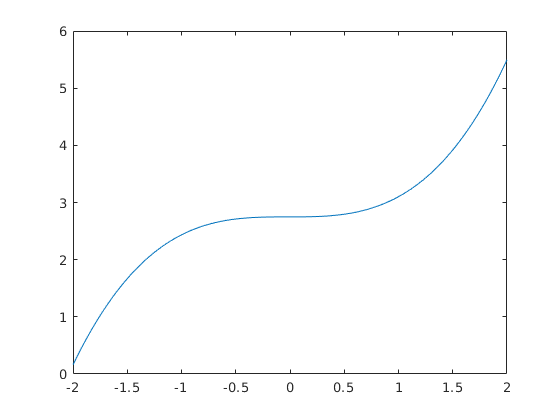

plot(x,Y)

Now, use the approximate derivative to get the original function, y back as *yhat *and plot it.  You may need to use/create another variable for the x axis when plotting.

## Excercise 6.  Anti-derivative.

yhat = diff(Y)

yhat =     0.1552    0.1488    0.1426    0.1366    0.1306    0.1248    0.1191    0.1136    0.1082    0.1029    0.0978    0.0928    0.0879    0.0831    0.0785    0.0740    0.0697    0.0654    0.0614    0.0574    0.0536    0.0499    0.0463    0.0429    0.0396    0.0364    0.0334    0.0305    0.0277    0.0251    0.0226    0.0202    0.0180    0.0158    0.0139    0.0120    0.0103    0.0087    0.0073    0.0060    0.0048    0.0037    0.0028    0.0020    0.0013    0.0008    0.0004    0.0001    0.0000    0.0000


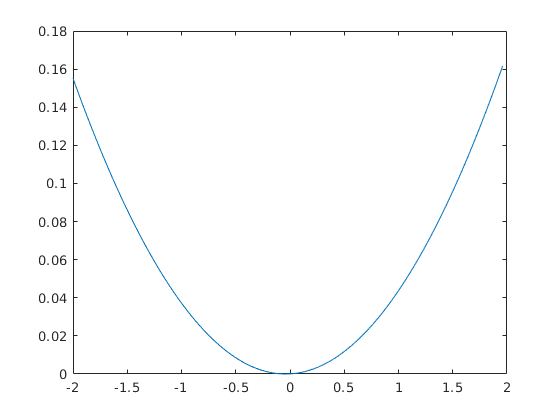

plot(xhat,yhat)

# Matrix

Matrix is closely related to vectors, and we have also explored some matrix operations last class. This class, we are going to explore 3 functions that are very useful but are hard to grasp for beginners, namely reshape, meshgrid, row-wise and column-wise operations.

## Reshape

When you are reshaping an array / matrix, the first dimension is filled first, and then the second dimension, so on and so forth

M = 1:100;
N1 = reshape(M,2,2,[]);    % It would create a 2*2*25 matrix
N2 = reshape(M,[2,2,25]);  % Same as N1
N2(:,:,25)                 % Gives you 97,98,99,100

ans =     97    99
    98   100


N2(:,1,25)                 % Gives you 97 and 98

ans =     97
    98


## Meshgrid

Meshgrid is quite hard to understand. Think of it as a way to replicate arrays, like the following example:

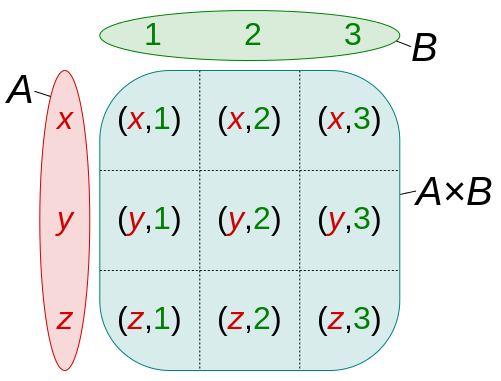

a = 1:3;
b = 1:5

b =      1     2     3     4     5


[A,B] = meshgrid(a,b) 

A =      1     2     3
     1     2     3
     1     2     3
     1     2     3
     1     2     3


B =      1     1     1
     2     2     2
     3     3     3
     4     4     4
     5     5     5


You have created two arrays A and B, note that in A, the vector a is copied row-wise, while the vector b is transposed and copied column-wise. This is useful, because when you lay one above the other, you essentially create a CARTESIAN PRODUCT, and it is useful when we need to plot a 3D graph: https://en.wikipedia.org/wiki/Cartesian_product 

Here is a more complicated example to show you when meshgrid is useful

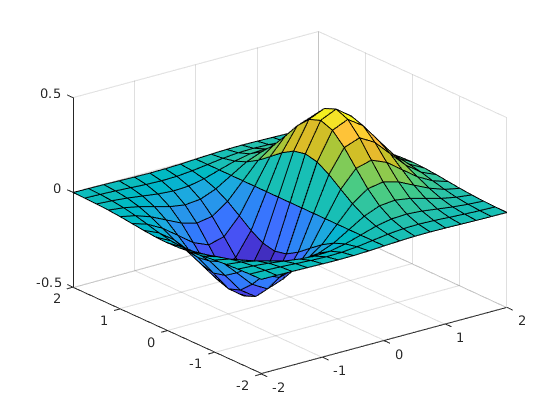

a1 = -2:0.25:2;
b1 = a1;
[A1,B1] = meshgrid(a1);
% Here we plot the surface of f(x) = x*exp^(x.^2+y.^2)
F = A1.*exp(-A1.^2-B1.^2);
surf(A1,B1,F)

## Row-wise / Column-wise operations

H = magic(4)     % create the magical matrix H

H =     16     2     3    13
     5    11    10     8
     9     7     6    12
     4    14    15     1


sum(H,1)         % column wise sum, note that this is a row vector(default)    

ans =     34    34    34    34


fliplr(H)        % flip H from left to right

ans =     13     3     2    16
     8    10    11     5
    12     6     7     9
     1    15    14     4


flipud(H)        % flip H upside down

ans =      4    14    15     1
     9     7     6    12
     5    11    10     8
    16     2     3    13


H(1,:) = fliplr(H(1,:)) % flip only ONE row upside down

H =     13     3     2    16
     5    11    10     8
     9     7     6    12
     4    14    15     1


H(1,:) = []      % delete the first column

H =      5    11    10     8
     9     7     6    12
     4    14    15     1


## Exercise 7 : Matrix Operations

% WRITEME: Create a random 4-by-5 matrix H2 with randi that draws random numbers from the set 1:20. Use help randi  
% WRITEME: Take the sum of second column of H2
% WRITEME: Take the average of the third row of H2
% WRITEME: reshape the 4-by-5 matrix into a 2-by-2-by-5 3D array, and name the array as C
% WRITEME: Delete the second row of each layer in C

# Control Sequence - For loops

Similar to other languages, MATLAB have if, while and for control sequences. For loops is one of the commonly used control sequences in MATLAB. We will continue the discussion of if and while in the next lesson

n = 1000;
D = zeros(1000);    % This is called pre-allocation
D(1) = 1;
D(2) = 2;
tic
for i = 3:n
    D(i) = D(i-1)+D(i-2);
end
toc

Elapsed time is 0.016497 seconds.


## BE CAREFUL!

For loops are considered the more inefficient type of operation in MATLAB Do not use it unless it is completely necessary. The action of using vectors to perform operations is called VECTORIZATION. You are going to explore more on computational efficiency in the next lesson.